# INTERFERENCE RESULTS

The following MATLAB script analizes the results obtained by a michelson interferometer while measuring the profile on the interference fringes generated experimentaly. 

clc; clf; clear

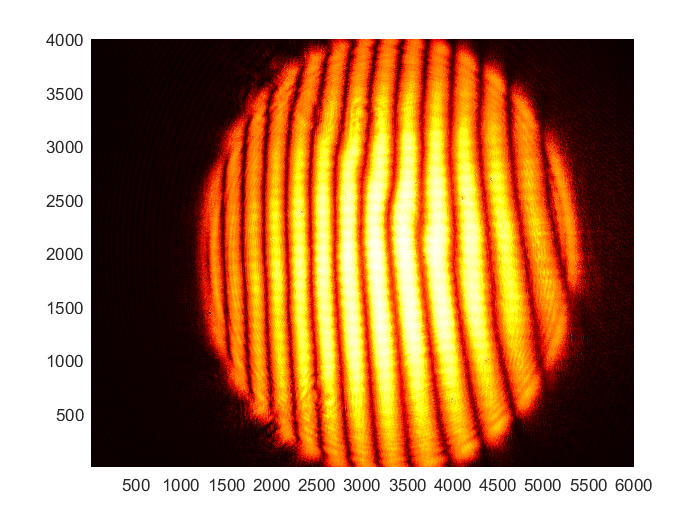

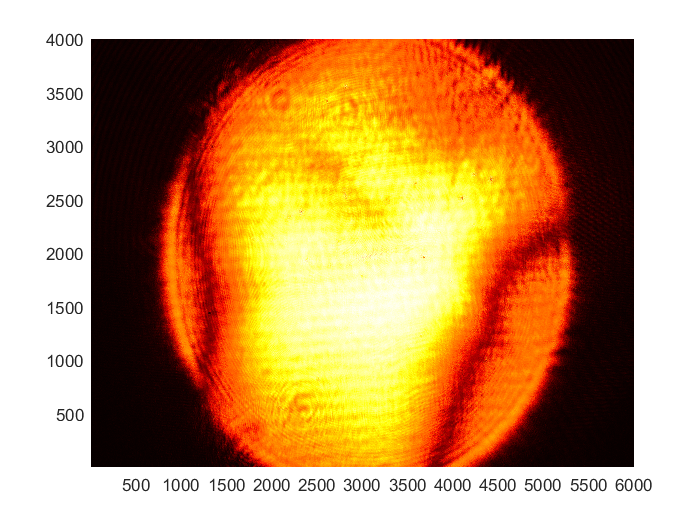

%Read picture
InterfPattern1_bnw = im2double(rgb2gray(imread("C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Michelson\Interference_Result2.JPG")));
InterfPattern2_bnw = im2double(rgb2gray(imread("C:\Users\6QV78LA_1909\OneDrive\Pictures\Saved Pictures\Latex\Figures_Optics\Interferometer_Michelson\Interference_Result1.JPG")));


## Extract a wave profile and integrate intensity:

This will prove that in destructive interference regions energy is not distroyed but rather it will be redistribiuted.

H0 = 2700; %Height of scan for both results

x1= linspace(1,length(InterfPattern1_bnw),length(InterfPattern1_bnw)); 
y1 = InterfPattern1_bnw(H0,:);

%Integrate over x space. 
I1=numericIntegration(y1); 
Res1 = sprintf("The total intensity is %1.1f [AU]",I1);

x2= linspace(1,length(InterfPattern2_bnw),length(InterfPattern2_bnw)); 
y2 = InterfPattern2_bnw(H0,:);

%Integrate over x space. 
I2 =numericIntegration(y2); 
Res2 = sprintf("The total intensity is %1.1f [AU]",I2);

## Plot results

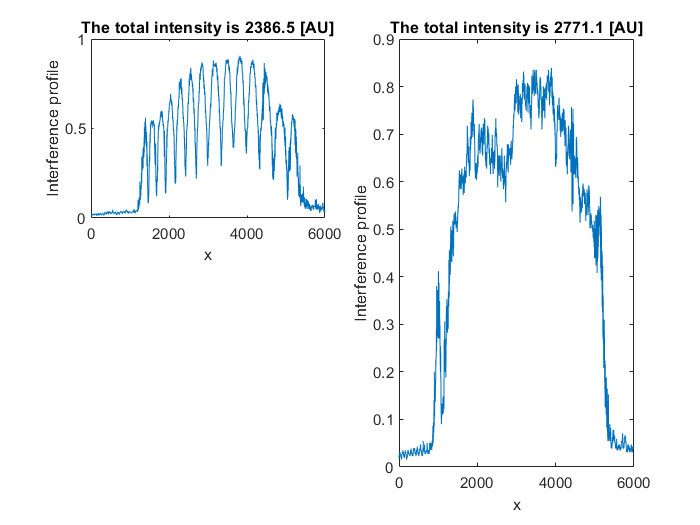

subplot(2,2,1)
plot(x1,y1)
xlabel("x")
ylabel("Interference profile")
title(Res1)

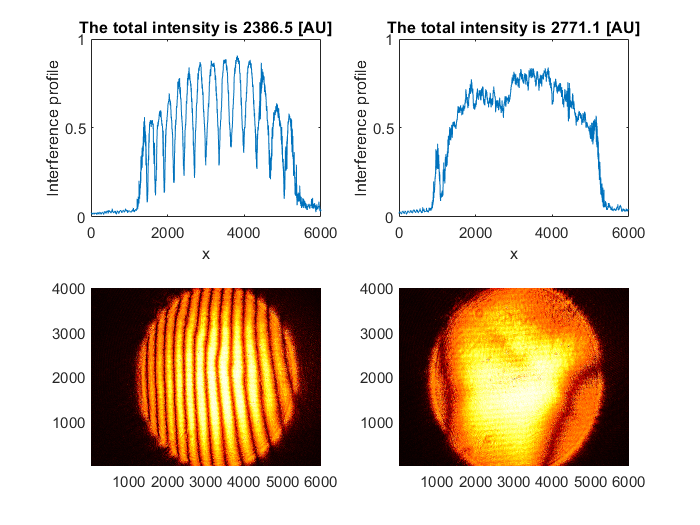

subplot(2,2,2)
plot(x2,y2)
xlabel("x")
ylabel("Interference profile")
title(Res2)
subplot(2,2,3)
pcolor(InterfPattern1_bnw)
colormap(hot)
shading interp
grid off
subplot(2,2,4)
pcolor(InterfPattern2_bnw)
colormap(hot)
shading interp
grid off

## Functions

function I = numericIntegration(A)
N = size(A,2);
I=0; %Initialize 

for ii = 1:1:N %Assuming descrete whole unitary values. 
    I = I + A(ii);
end
    
end